Fs = 44100;
sample_num = 10;
duration = 5;

files_struct = dir('*.mp3');
files_table = struct2table(files_struct);
songs = string(files_table.name);
num = length(songs);
data = zeros(num * sample_num, Fs * duration);
y = zeros(num * sample_num, 2); 


for i = 1:num
    [v,] = audioread(songs(i));
    v = v(10*Fs:length(v) - 10*Fs - 1, 1);
    r = ceil(rand(1, sample_num) .* (length(v) - duration * Fs));
    hiphop = contains(songs(i),'Hiphop');
    rb = contains(songs(i), 'RB');
    jazz = contains(songs(i), 'Jazz');
    otis = contains(songs(i), 'Otis');
    maxwell = contains(songs(i), 'Maxwell');
    quincas = contains(songs(i), 'Quincas');
    if otis == 1
        y((i - 1) * sample_num + 1:i * sample_num, 1) = 1;
    elseif maxwell == 1
        y((i - 1) * sample_num + 1:i * sample_num, 1) = 2;
    elseif quincas == 1
        y((i - 1) * sample_num + 1:i * sample_num, 1) = 3;
    end
    
    if hiphop == 1
        y((i - 1) * sample_num + 1:i * sample_num, 2) = 1;
    elseif rb == 1
        y((i - 1) * sample_num + 1:i * sample_num, 2) = 2;
    elseif jazz == 1
        y((i - 1) * sample_num + 1:i * sample_num, 2) = 3;
    end
    
    for j = 1 : 10
        head = r(1, j);
        data((i - 1) * sample_num + j, :) = v(head:head + Fs*duration - 1, 1);
    end
end


total_sample = length(data(:, 1));
r = randperm(total_sample);
train = data(r(1:total_sample * 0.7), :);
train_y = y(r(1:total_sample * 0.7), :);
test = data(r(total_sample * 0.7 + 1 : total_sample * 0.9), :);
test_y = y(r(total_sample * 0.7 + 1 : total_sample * 0.9), :);
vali = data(r(total_sample * 0.9 + 1:end), :);
vali_y = y(r(total_sample * 0.9 + 1:end), :);

%{
for i = 1:length(data)
    clip = audioplayer(data(i, :), Fs);
    playblocking(clip); 
end
    %}

% within [0, 1]
compression_rate = 1;

band1 = train(train_y(:,2) == 1, :);
band1_com = band1(:,1:1/compression_rate:end);

band2 = train(train_y(:,2) == 2, :);
band2_com = band2(:,1:1/compression_rate:end);

band3 = train(train_y(:,1) == 3, :);
band3_com = band3(:,1:1/compression_rate:end);

min_l = min([length(band1(:,1)),length(band2(:,1)),length(band3(:,1))]);

band1_com = band1_com(1:min_l,:);
band2_com = band2_com(1:min_l,:);
band3_com = band3_com(1:min_l,:);


band1_com = band1_com';
band2_com = band2_com';
feature = 30;


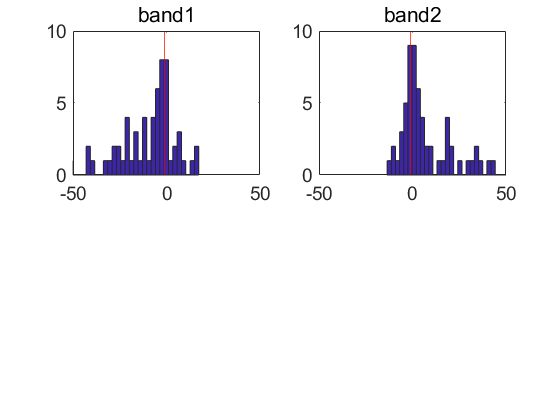


[result,w,U,S,V,threshold] = band_trainer(band1_com,band2_com,feature);

test1 = test(test_y(:,2) ~= 3, :)

test1 =    -0.3088   -0.3125   -0.3135   -0.3107   -0.3094   -0.3067   -0.2961   -0.2871   -0.2845   -0.2800   -0.2746   -0.2686   -0.2598   -0.2552   -0.2551   -0.2542   -0.2547   -0.2538   -0.2514   -0.2532   -0.2558   -0.2567   -0.2584   -0.2580   -0.2552   -0.2515   -0.2463   -0.2433   -0.2428   -0.2395   -0.2336   -0.2294   -0.2293   -0.2312   -0.2305   -0.2278   -0.2243   -0.2193   -0.2153   -0.2117   -0.2076   -0.2045   -0.1979   -0.1897   -0.1869   -0.1834   -0.1769   -0.1751   -0.1762   -0.1755
    0.6266    0.6142    0.6035    0.5949    0.5893    0.5857    0.5831    0.5810    0.5774    0.5730    0.5707    0.5715    0.5737    0.5733    0.5676    0.5601    0.5538    0.5467    0.5380    0.5279    0.5169    0.5059    0.4945    0.4821    0.4678    0.4506    0.4321    0.4141    0.3977    0.3840    0.3713    0.3566    0.3391    0.3138    0.2754    0.2304    0.1915    0.1643    0.1457    0.1287    0.1089    0.0871    0.0652    0.0429    0.0203    0.0003   -0.0179   -0.0402   -0.0662 

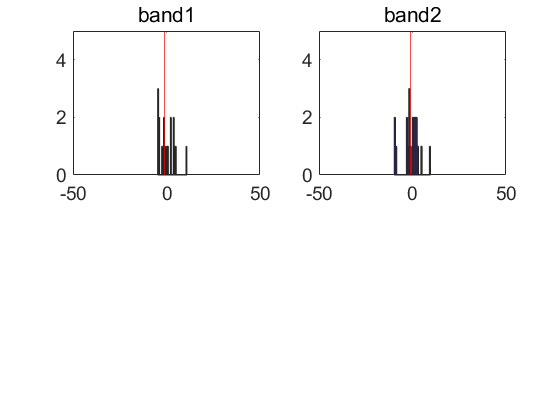

test1_y = test_y(test_y(:,2) ~= 3, 2);
test_mat = U'*test1';
pval = w'*test_mat;
ResVec = (pval>threshold);

test1_1 = w'*(U'*test(test_y(:,2) == 1, :)');
test1_2 = w'*(U'*test(test_y(:,2) == 2, :)');
close all
figure(2)
subplot(2,2,1)
hist(test1_1,30); hold on, xline(threshold, 'r');
set(gca,'Xlim',[-50 50],'Ylim',[0 5],'Fontsize',[14])
title('band1')
subplot(2,2,2)
hist(test1_2,30,'r'); hold on, xline(threshold, 'r');

set(gca,'Xlim',[-50 50],'Ylim',[0 5],'Fontsize',[14])
title('band2')

corr = 0;
for i=1:length(test1(:,1))
    if (test1_y(i) == 1 && ResVec(i) == 0)
        corr = corr + 1;
    end
    
    if (test1_y(i) == 2 && ResVec(i) == 1)
        corr = corr + 1;
    end
    
end

corr / length(test1(:,1))

ans = 0.5000